%This is the main script that graphs the torque vs. ramp angle
%relationship.
n = 100; %number of data points

% CONSTANTS ==============
v = 5; % Turn Velocity of the vehicle (Tangential) m/s (maybe ft/s? Im not sure ask Jesse)
R = 10; % Turn Radius (from center of turn to center of vehicle) meters (ft?)
coeffFriction = 1.35; % between ground and wheel
rWheel = 0.5; % [m] This nees to be consistent with the calcTorque script
massOfVehicleLbm = 630; % lbm
widthOfVehicle = 2.0 % [m] Also needs to be in sync with calcTorque

widthOfVehicle = 2

comHeight = 13.2 * 0.0254 % [m] Height of center of mass above ground

comHeight = 0.3353

% END CONSTANTS =============
theta_deg = linspace(15, 60, n)

theta_deg =    15.0000   15.4545   15.9091   16.3636   16.8182   17.2727   17.7273   18.1818   18.6364   19.0909   19.5455   20.0000   20.4545   20.9091   21.3636   21.8182   22.2727   22.7273   23.1818   23.6364   24.0909   24.5455   25.0000   25.4545   25.9091   26.3636   26.8182   27.2727   27.7273   28.1818   28.6364   29.0909   29.5455   30.0000   30.4545   30.9091   31.3636   31.8182   32.2727   32.7273   33.1818   33.6364   34.0909   34.5455   35.0000   35.4545   35.9091   36.3636   36.8182   37.2727


theta = deg2rad(theta_deg); %Ramp Angle, radians (0 to 60 deg)
massOfVehicle = massOfVehicleLbm * 0.4546; % kg

Fnormal = massOfVehicle * 9.81/4; %Wheel normal force, in lbs. 630lbs is the whole vehicle weight + driver.

% divide by 2 b/c load distribution across front and back wheels
FN_centrifugal_diff = massOfVehicle * v ^2 * comHeight / R / widthOfVehicle / 2; 

FN_left = Fnormal - FN_centrifugal_diff; % normal force on left wheels; turning left
FN_right = Fnormal + FN_centrifugal_diff

FN_right = 762.4058

I derived the max allowable force from wheel that doesn't cause slipping to be:

$\sqrt{(\mu F_N)^2 - \left(\frac{mv^2}{4R}\right)^2} = F_{torque}$  where $\frac{mv^2}{4R}$ is the centripetal force on each wheel. 

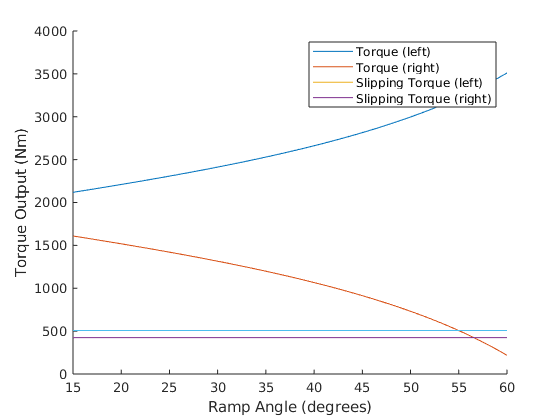

% Assume that right wheels are responsible for avoiding slip
FslipRight = sqrt((coeffFriction * FN_right)^2 - (massOfVehicle * v^2 / (4 * R))^2);
TslipRight = FslipRight * rWheel; %Convert the maximum allowable thrust to torque

FslipLeft  = sqrt((coeffFriction * FN_left)^2  - (massOfVehicle * v^2 / (4 * R))^2);
TslipLeft = FslipLeft* rWheel; %Convert the maximum allowable thrust to torque


torqueOutputs = zeros(3,n); %Initialize the output array

for i = 1:n
    %Loop over the calcTorque function to calculate T2, T3 and isFpre for
    %each theta
    [T2, T3, Fpre] = calcTorque(R, v, theta(i));
    torqueOutputs(1, i) = T2;
    torqueOutputs(2, i) = T3;
    torqueOutputs(3, i) = Fpre;
end

T2array = torqueOutputs(1, :); %Store the simulation output into different
T3array = torqueOutputs(2, :); %arrays for plotting
FpreBoolArray = torqueOutputs(3, :);

%Plotting the outputs, y-axis is the torque and x-axis is the ramp angle in
%radians
clf
hold on

plot(theta_deg, T2array)  %Plotting left wheel torque graph (left)
plot(theta_deg, T3array)  %Plotting left wheel torque graph (right)
xlabel('Ramp Angle (degrees)')
ylabel('Torque Output (Nm)')
plot(theta_deg, TslipLeft * ones(length(T2array)));
plot(theta_deg, TslipRight* ones(length(T2array)));
legend('Torque (left)','Torque (right)', 'Slipping Torque (left)', 'Slipping Torque (right)')


hold off

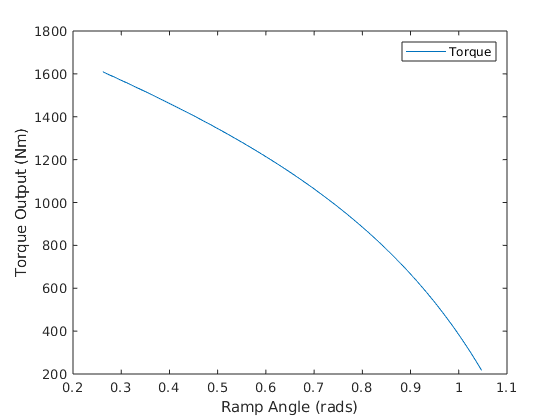

clf
plot(theta, T3array)  %Plotting right wheel torque graph
xlabel('Ramp Angle (rads)')
ylabel('Torque Output (Nm)')
legend('Torque');